# Integration by Parts

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Integration by parts is an extremely powerful method of integration that will only come into full focus once you apply it to solving differential equations. For the moment, however, it will allow you to solve some integrals that substitution is no help with. 

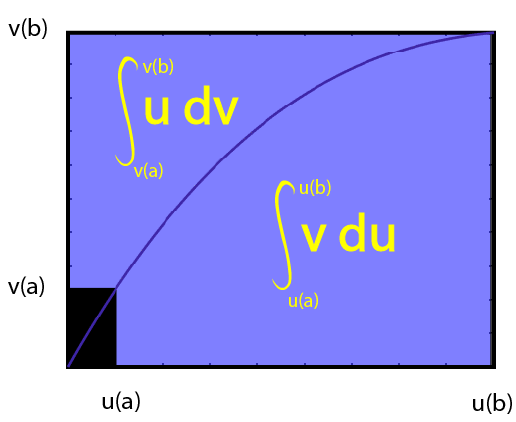

Integration by parts allows you to subdivide your integrand into integrated and differentiated components and recombine those pieces in ways that can be easier to compute.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Integration by Parts Geometrically

Consider the relationship given by the product rule for derivatives:


$$\frac{d}{dt}\left[u(t)\cdot v(t)\right] = u(t)\cdot \frac{dv}{dt} + \frac{du}{dt}\cdot v(t).\;\;\;\;\;\;\; (\star)$$


By applying the [Fundamental Theorem of Calculus](matlab:open('./FundamentalTheorem.mlx')) and linearity, we can see that


$$\int_a^b \frac{d}{dt}\left[u(t)\cdot v(t)\right] \; dt = \int_a^b u(t)\cdot \frac{dv}{dt} \; dt + \int_a^b \frac{du}{dt}\cdot v(t)\; dt \;\;\;\;\;\;\; (1)$$
   


$$u(b)v(b)-u(a)v(a) = \int_{a}^{b}u(t)\cdot\frac{dv}{dt}\;dt + \int_{a}^{b}v(t)\cdot \frac{du}{dt}\;dt \;\;\;\;\;\;\; (2)$$
   

To understand the geometry, we are going to look at, let's express equation (2) in a slightly different way. Notice that 


$$\frac{dv}{dt}\; dt = \lim_{dt \to 0} \frac{v(t+dt)-v(t)}{dt}\cdot dt = \lim_{dt \to 0} v(t+dt)-v(t) = dv,$$


where $dv$ is the change in the value of $v$ as that change approaches $0$! If we also note that, where the functions are invertible, we can write $u(v)$ and $v(u)$, this means we could say:


$$u(b)v(b)-u(a)v(a) = \int_{v(a)}^{v(b)}u(v)\;dv + \int_{u(a)}^{u(b)}v(u)\; du \;\;\;\;\;\;\; (3)$$


The left-hand side of equation $(3)$ is the difference of the two rectangles while the right-hand side of equation $(3)$ subdivides the same region into a sum of two pieces divided by the curve $(u,v)$. Practically, expressing $u$ as a function of $v$ or vice versa may be complex algebraically, but is straightforward geometrically using the parametrization in terms of $t$:

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
 
tl = tiledlayout(1,2); %#ok<NASGU> 
tVals = -5:.01:5;
uVals = u(tVals);
vVals = v(tVals);
nexttile
plot(uVals,vVals)
title("Plotting $v$ against $u$","Interpreter","latex")
xlabel("$u(t)$","Interpreter","latex")
ylabel("$v(t)$","Interpreter","latex")
axis square
nexttile
plot(vVals,uVals)
title("Plotting $u$ against $v$","Interpreter","latex")
xlabel("$v(t)$","Interpreter","latex")
ylabel("$u(t)$","Interpreter","latex")
axis square
% Add layout title
% title(tl,"Thinking in Curves: Two Rotations/Reflections of $u$ and $v$","Interpreter","latex")
% subtitle(tl,"$t \in [-5,5]$","Interpreter","latex")

In many cases, including with $u(t) = t^2$ and $v(t) = 1-\cos(t)$, one or more of the resulting plots are not functions. A sufficient restriction of the domain, however, will result in a functional relationship for any sufficiently nice parametrized functions $u(t)$ and $v(t)$. 

  **Try**. Can you restrict the domain from $t=a$ to $t=b$ such that both $u(v)$ and $v(u)$ are $1:1$ functions over that domain?

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
a = -5;
b = 5;
 
tl = tiledlayout(1,2);
if a < b
    tVals = a:.01:b;
else
    warning("You should choose a < b.")
    tVals = b:.01:a;
end
uVals = u(tVals);
vVals = v(tVals);
nexttile
plot(uVals,vVals)
title("Plotting $v$ as a function of $u$","Interpreter","latex")
xlabel("$u(t)$","Interpreter","latex")
ylabel("$v(t)$","Interpreter","latex")
axis square
nexttile
plot(vVals,uVals)
title("Plotting $u$ as a function of $v$","Interpreter","latex")
xlabel("$v(t)$","Interpreter","latex")
ylabel("$u(t)$","Interpreter","latex")
axis square
% Add layout title
% title(tl,"Thinking in Curves: Two Rotations/Reflections of $u$ and $v$","Interpreter","latex")
% subtitle(tl,"$t \in ["+a+","+b+"]$","Interpreter","latex")

  **Try**.

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
a = 1;
b = 3;
 
if a>b
    disp("This code requires that b>a. Your endpoints have been reversed.")
    ar = b;
    br = a;
else
    ar = a;
    br = b;
end
tVals = ar:.01:br;
numSteps = length(tVals);
uVals = u(tVals);
vVals = v(tVals);
z = zeros(size(tVals));
p = plot(uVals,vVals);
title("Geometric Integration by Parts")
hold on
xlabel("u(t)")
ylabel("v(t)")
v0 = double(v(0));
u0 = double(u(0));
[hx,hy,dUPosRegions,dUNegRegions,dULines] = PlotRegions(vVals,uVals,v0,["r" "b"],"h");
[vx,vy,dVPosRegions,dVNegRegions,dVLines] = PlotRegions(uVals,vVals,u0,["r" "b"],"v");
rectGrp = DrawRectangles(uVals,vVals,u0,v0);
surface([uVals;uVals],[vVals;vVals],[z;z],[tVals;tVals],...
    "FaceColor","none","EdgeColor","interp","LineWidth",2)
hold off
SetXTicks(p.Parent,double([u(ar) u(br)]),["u(a)" "u(b)"])
SetYTicks(p.Parent,double([v(ar) v(br)]),["v(a)" "v(b)"])

showPosdUReg = true; showNegdUReg = true;
showPosdVReg = false; showNegdVReg = false;
showRectSubs = true; hideVertStripes = false;    hideHorizStripes = true;
if showPosdUReg
    dUPosRegions.Visible = "on";
else
    dUPosRegions.Visible = "off"; %#ok<*UNRCH> 
end
if showNegdUReg
    dUNegRegions.Visible = "on";
else
    dUNegRegions.Visible = "off";
end
if showPosdVReg
    dVPosRegions.Visible = "on";
else
    dVPosRegions.Visible = "off";
end
if showNegdVReg
    dVNegRegions.Visible = "on";
else
    dVNegRegions.Visible = "off";
end
if hideVertStripes
    dULines.Visible = "off";
else
    dULines.Visible = "on";
end
if hideHorizStripes 
    dVLines.Visible = "off";
else
    dVLines.Visible = "on";
end
if showRectSubs
    rectGrp.Visible = "on";
else
    rectGrp.Visible = "off";
end

  **Try**.

- What if you keep the default values of $u(t) = t$ and $v(t) = 1-\cos(t)$ but change the domain of integration from $a = 0$ to $b=3$ to be $a=0$ to $b=5$? 

- What if you use $u(t) = t^2$ and $v(t) = \sin^2(t)$ with $a=0$ to $b=3$?

- What if you use $u(t) = e^t$ and $v(t) = t$ with any values of $a$ and $b$?

- What if you use $u(t) = e^t$ and $v(t) = t^2$ with $a=0$ and $b=5$? Or $a=-3$ and $b=3$?

## Integration by Parts Algebraically

Starting with the product rule for derivatives in equation $(\star)$ and reordering the parts, we have:


$$u(t)\cdot \frac{dv}{dt} = \frac{d}{dt}\left[u(t)\cdot v(t)\right] - \frac{du}{dt}\cdot v(t) .$$


Integrating, this becomes


$$\int u(t)\cdot \frac{dv}{dt}\; dt = \int \frac{d}{dt}\left[u(t)\cdot v(t)\right] - \frac{du}{dt}\cdot v(t)\; dt$$



$$\int u(t)\cdot \frac{dv}{dt}\; dt = \int \frac{d}{dt}\left[u(t)\cdot v(t)\right]\; dt - \int v(t) \frac{du}{dt}\; dt$$



$$\int u(t)\cdot \frac{dv}{dt}\; dt = u(t)\cdot v(t) - \int v(t) \frac{du}{dt}\; dt \;\;\;\;\;\;\; (\diamond)$$


This is frequently shortened to $\int u\; dv = uv-\int v\; du$. This is important because it lets us replace components we may not know how to integrate (like $u(t)$) with terms that may be easier to work with (like $\frac{du}{dt}$). This does require that the remaining part of the integrand, expressed here as $\frac{dv}{dt}$ is an integrable function.

## Identifying integrable and differentiable components

### Powers and Logarithms

When there is a natural logarithm in an integrand that doesn't exist as part of a substitution, the only exact method available is to use integration by parts with the natural logarithm as $u$ in equation $(\diamond)$. 

**Example:** $\int t^{3/4}\ln(t)\; dt$

Let $u(t) = \ln(t)$ so then $\frac{dv}{dt} = t^{3/4}$. This means that 


$$\frac{du}{dt} = \frac{d}{dt}\left[\ln(t)\right] = \frac{1}{t}$$
 

and 


$$v(t) = \int \frac{dv}{dt}\; dt = \int t^{3/4}\; dt = \frac{4}{7}t^{7/4}.$$


Putting all of these pieces together into equation $(\diamond)$, we have


$$\int t^{3/4}\ln(t)\; dt = \ln(t)\cdot \frac{4}{7}t^{7/4}-\int \frac{4}{7}t^{7/4}\cdot \frac{1}{t}\; dt$$
 

which evaluates to 


$$\int t^{3/4}\ln(t)\; dt = \frac{4}{7}t^{7/4}\ln(t) - \frac{4}{7}\int t^{3/4}\; dt$$


                        
$$= \frac{4}{7}t^{7/4}\ln(t)-\frac{16}{49}t^{7/4}+C$$


                     
$$= \frac{4}{7}t^{7/4}\left(\ln(t)-\frac{4}{7}\right)+C$$


#### Practice

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declare symbolic variables
    varOpts = [t r x z];                 % Define the list of variables to use in the problems
end
    [myFun,varChoice] = GenProbType(varOpts,3);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
assume(varChoice>0)
Check1(myFun,varChoice,myAnswer);
                          % Run this section

### Polynomials and Cosines, Sines or Exponentials

If we integrate sines and/or cosines, we find cosines and/or sines. If we integrate exponentials, we find ourselves with multiples of the same exponential remaining. This means that if we choose $\frac{dv}{dt}$ to involve sines, cosines or exponentials, the resulting $v$ will not be any more difficult to integrate than the original, although it will not be any simpler either. However, if this repeatedly integrable term is multiplied by an $n^{\text{th}}$ degree polynomial, then with $n$ applications of integration by parts the polynomial term will disappear leaving only the integrable function behind.

**Example: **$\int (x^2-3x+7)\cos(4x)\; dx$

Apply equation $(\diamond)$ with  $\frac{dv}{dx} = \cos(4x)$ and $u = x^2-3x+7$ so we have $v = -\frac{1}{4}\sin(4x)$ and $\frac{du}{dx} = 2x-3$. Recombining into the first integration by parts we have:


$$\int (x^2-3x+7)\cos(4x)\; dx = -\frac{(x^2-3x+7)}{4}\sin(4x)+\frac{1}{4}\int (2x-3)\sin(4x)\; dx$$


Repeating this procedure, we have $\frac{dv}{dx} = \sin(4x)$ and $u(x) = 2x-3$ so $v = -\frac{1}{4}\cos(4x)$ and $\frac{du}{dx} = 2$. Recombining into equation $(\diamond)$ we have:


$$\int (x^2-3x+7)\cos(4x)\; dx = -\frac{(x^2-3x+7)}{4}\sin(4x)+\frac{1}{4}\left[\frac{(3-2x)}{4}\cos(4x)+\frac{1}{2}\int\cos(4x)\; dx\right]$$


                                   
$$= -\frac{(x^2-3x+7)}{4}\sin(4x)+\frac{(3-2x)}{16}\cos(4x)+\frac{1}{32}\sin(4x)+C$$


#### Practice

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declare symbolic variables
    varOpts = [t r x z];                 % Define the list of variables to use in the problems
end
    [myFun,varChoice] = GenProbType(varOpts,2);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
assume(varChoice>0)
Check1(myFun,varChoice,myAnswer);
                          % Run this section

### Cosines, Sines, and Exponentials

If you are trying to integrate a product of sines, cosines, or exponentials, then you can choose either component to be $u$ or $v$, but you will need to pay close attention to the form of your integral at each step. These integrals are solved using both algebra and integration by parts.

**Example: **$\int  \cos(4t-3)e^{-7t}\; dt$

Let $u = \cos(4t-3)$ and $\frac{dv}{dt} = e^{-7t}$. Then $\frac{du}{dt} = -4\sin(4t-3)$ and $v = -\frac{1}{7}e^{-7t}$. Thus,


$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}-\frac{4}{7}\int\sin(4t-3)e^{-7t}\; dt.$$
 

Applying equation $(\diamond)$ again with $u = \sin(4t-3)$ and $\frac{dv}{dt} = e^{-7t}$ so $\frac{du}{dt} = 4\cos(4t-3)$ and $v = -\frac{1}{7}e^{-7t}$ we have

        
$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}-\frac{4}{7}\left[-\frac{1}{7}\sin(4t-3)e^{-7t}+\frac{4}{7}\int \cos(4t-3)e^{-7t}\; dt\right]$$


   
$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}+\frac{4}{49}\sin(4t-3)e^{-7t}-\frac{16}{49}\int \cos(4t-3)e^{-7t}\; dt$$
 

Observe that the original integral is now present on both sides of the equation. Combining them and simplifying, we have:


$$\int \cos(4t-3)e^{-7t}\; dt + \frac{16}{49}\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}+\frac{4}{49}\sin(4t-3)e^{-7t}$$
                                                                                             


$$\frac{65}{49}\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}+\frac{4}{49}\sin(4t-3)e^{-7t}$$
                                            


$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{7}{65}\cos(4t-3)e^{-7t}+\frac{4}{65}\sin(4t-3)e^{-7t} + C$$
        

#### Practice

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declare symbolic variables
    varOpts = [t r x z];                 % Define the list of variables to use in the problems
end
    [myFun,varChoice] = GenProbType(varOpts,4);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
assume(varChoice>0)
Check1(myFun,varChoice,myAnswer);
                          % Run this section

## Integration by Parts can generate surprising results

Unlike the other simple methods of integration, integration by parts is unique in that it can be applied to every integrable function. The trouble is that the resulting equivalent expression may or may not be helpful in determining the value. 

#### Stick to one choice

If you switch components between multiple applications of integration by parts you can prove true statements that are equivalent to $0=0$. If you do encounter this type of result, go back and check each of your choices for $u$ and $\frac{dv}{dx}$. 

**Example **$\int x^2e^x\; dx$

Apply equation $(\diamond)$ with $u = x^2$ and $\frac{dv}{dx} = e^x$. Then $\frac{du}{dx} = 2x$ and $v = e^x$, so


$$\int x^2e^x\; dx = x^2e^x-2\int xe^x\; dx$$


We're not done, so apply equation $(\diamond)$ again with $u = e^x$ and $\frac{dv}{dx} = x$ so $\frac{du}{dx} = e^x$ and $v = \frac{x^2}{2}$. Plugging these values in we have

$\int x^2e^x\; dx = x^2e^x - 2\left[e^x\left(\frac{x^2}{2}\right) - \frac{1}{2}\int x^2e^x\; dx\right].$ Simplifying, this becomes 


$$\int x^2e^x\; dx = x^2e^x-e^xx^2+\int x^2e^x$$
 

or in other words, $\int x^2 e^x\; dx = \int x^2 e^x \; dx$ or $0=0$. True, but not satisfying if we're trying to determine the value of the integral. This will occur if you switch the portions of the integrand that are representing the $u$ and $v$ components in subsequent applications of equation $(\diamond)$. 

#### Functions defined by their integrals

In other cases, the equations you discover by integration by parts can relate to more complicated functions defined in terms of integrals. You are unlikely to recognize these unless you are checking an integral calculator or know that you are in a domain where a particular special integral function is likely to occur. 

**Example **$\int \ln(x)\sin(x)\; dx$

Apply equation $(\diamond)$ with $u(x) = \ln(x)$ and $\frac{dv}{dx} = \sin(x)$. Then we have


$$\int \ln(x)\sin(x)\; dx = -\ln(x)\cos(x)+\int \frac{\cos(x)}{x}\; dx.$$


In fact, this is the best we can do with the tools available. For further details you can see the [MATLAB documentation on cosint](https://www.mathworks.com/help/symbolic/sym.cosint.html) or the Wikipedia page on [trigonometric integrals](https://en.wikipedia.org/wiki/Trigonometric_integral).

**Example** $\int t^{-3/2}\cos(t)\; dt$

Apply equation $(\diamond)$ with $u = t^{-3/2}$ and $\frac{dv}{dt} = \cos(t)$. Then $\frac{du}{dt} = -\frac{3}{2}t^{-5/2}$ and $v(t)= \int \cos(t)\; dt = \sin(t)$. This gives us


$$\int t^{-3/2}\cos(t)\; dt = -\frac{3}{2}t^{-5/2}\sin(t) + \int \frac{3}{2}t^{-5/2}\sin(t)\; dt.$$


This is true, but not actually helpful because the comprehensible solution in terms of a [Fresnel integral](https://www.mathworks.com/help/symbolic/sym.fresnelc.html) requires making the opposite choice with $\frac{dv}{dt} = t^{-3/2}$ and $u = \cos(t)$.

## Practice Randomized Integration by Parts Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

% Clear variables that may be reused in other parts of this module
clear errorCount totIPProbs totAttempts adjustcount lastFive myFun varChoice
syms t r x z C                       % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totIPProbs = 0;                    % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Integration by Parts Practice.")

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totIPProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = GenProbType(varOpts,1);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totIPProbs = totIPProbs+1;     % Increase the count of total problems attempted
end
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totIPProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

 
AnalyzeResults(totIPProbs,errorCount,totAttempts,adjustCount,lastFive)

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Integration by Parts" in the Integrals section. The app will open in a new window.

[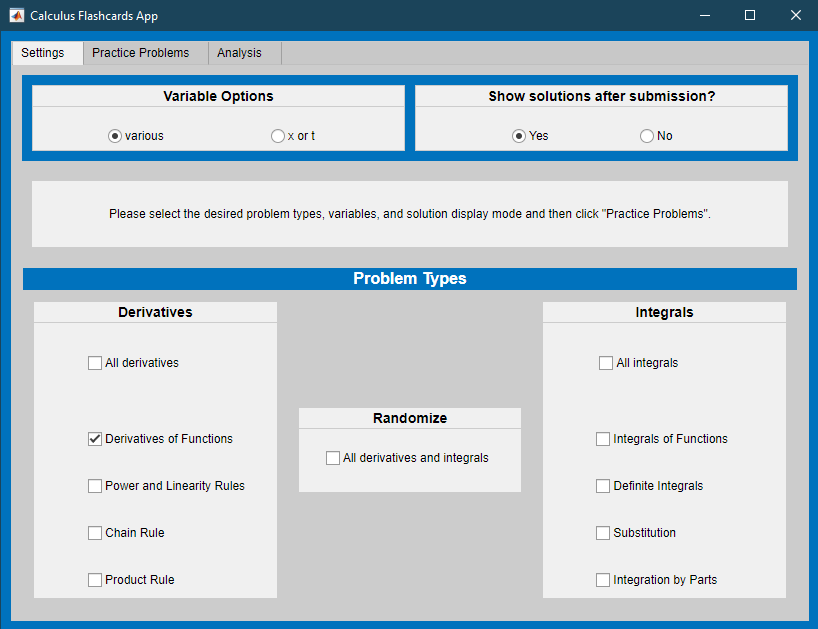](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

**Create visualizations of Integration by Parts**

Plot regions

function [x,y,posRegGroup,negRegGroup,LinesGroup] = PlotRegions(fVals,dVals,f0,cols,hvflag)
posRegGroup = hggroup;
negRegGroup = hggroup;
LinesGroup = hggroup;
regGrpChoice = [negRegGroup posRegGroup];
dU = double(dVals(2:end)-dVals(1:end-1));
posDU = dU >= 0;
posF = double(fVals(1:end-1))>=0;
fSignChange = posF(2:end)-posF(1:end-1);
fSignChangeIdx = find(fSignChange~=0);
dUSignChange = (posDU(2:end)-posDU(1:end-1));
dUSignChangeIdx =  find(dUSignChange~=0);
dUSignChangeIdx = [1 (dUSignChangeIdx + 1) length(dVals)];
scIdx = unique(sort([dUSignChangeIdx fSignChangeIdx]),"sorted");
scVal = (posDU(scIdx(1:end-1))==posF(scIdx(1:end-1)))+1;
alphaVal = 1/(length(scIdx)-1);
for k = 1:length(scIdx)-1
    xU = dVals(scIdx(k):scIdx(k+1)-1);
    x = double([xU flip(xU)]);
    yV = fVals(scIdx(k):scIdx(k+1)-1);
    y = double([f0*ones(size(yV)) flip(yV)]);
    if hvflag == "h"
        patch(x,y,cols(scVal(k)),"FaceAlpha",alphaVal,"Parent",regGrpChoice(scVal(k)));
        LinesGroup = AddStripes(x,y,"v",10,LinesGroup);
    else
        patch(y,x,cols(scVal(k)),"FaceAlpha",alphaVal,"Parent",regGrpChoice(scVal(k)));
        LinesGroup = AddStripes(x,y,"h",10,LinesGroup);
    end
end
end

Add stripes

function lineGroup = AddStripes(x,y,hvflag,step,lineGroup)
    % x and y are the same length, so this is just determining the bin
    % index value based on the relative sizes of the number of rectangles
    % length(x)/2 and step
    idx = DefStripes(length(x)/2,step);
    if length(idx)>1
        if hvflag == "v"       
            try
                p = plot([x(idx(1)) x(idx(1))],[y(idx(1)) y(end-idx(1))],"Parent",lineGroup,SeriesIndex="none");
            catch
                p = plot([x(idx(1)) x(idx(1))],[y(idx(1)) y(end-idx(1))],"k","Parent",lineGroup);
            end
            for k = 2:length(idx)
                copyobj(p,lineGroup)
                lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
                lineGroup.Children(k).YData = [y(idx(k)) y(end-idx(k))];
            end
            drawnow
        else
            try
                p = plot([x(idx(1)) x(end-idx(1))],[y(idx(1)) y(idx(1))],"Parent",lineGroup,SeriesIndex="none");
            catch
                p = plot([x(idx(1)) x(end-idx(1))],[y(idx(1)) y(idx(1))],"k","Parent",lineGroup);
            end
            for k = 2:length(idx)
                copyobj(p,lineGroup)
                lineGroup.Children(k).XData = [y(idx(k)) y(end-idx(k))];
                lineGroup.Children(k).YData = [x(idx(k)) x(idx(k))];
            end
            drawnow
        end
    end
end

function idx = DefStripes(numRect,step)
    numBins = floor(numRect/step);
    if numRect > step
         rem = mod(numRect,step);
         if (rem == 0) && (numBins > 0)
             idx = 0:step:numRect;
             idx(1) = 1;
         elseif numBins >= rem
             intro = 1:(step+1):floor(rem/2)*(step+1);
             middle = floor(rem/2)*(step+1):step:(numRect-(step+1)*ceil(rem/2));
             last = (numRect-(step+1)*ceil(rem/2)):step+1:numRect;
             idx = [intro middle(2:end-1) last];
         else
            idx = 1:(ceil(rem/numBins)+step):numRect;
            if idx(end) ~= numRect
                idx = [idx numRect];
            end
         end
    else
        idx = unique([1 numRect]);
    end
end

Draw rectangles

function rectObj = DrawRectangles(uVals,vVals,u0,v0)
rectObj = hggroup;
ua = double(uVals(1));
ub = double(uVals(end));
va = double(vVals(1));
vb = double(vVals(end));
ax = gca;
col = colormap;
fgcol = round(ax.Parent.Color); % main figure color pinned to white/black
bkcol = round(ax.GridColor); % accent color pinned to black/white
if (ua>u0)~=(va>v0)
    fCol = fgcol;
else
    fCol = bkcol;
end
if (ub>u0)~=(vb>v0)
    lCol = col(3,:); % 3rd accent color, generally yellow
else
    lCol = bkcol;
end
rectangle("Position",[min(u0,ua) min(v0,va) abs(ua-u0) abs(va-v0)],...
    "FaceColor",fCol,"EdgeColor",bkcol,"LineWidth",2,"Parent",rectObj);
rectangle("Position",[min(u0,ub) min(v0,vb) abs(ub-u0) abs(vb-v0)],...
    "FaceColor","none","LineWidth",3,"Parent",rectObj,"EdgeColor",lCol);
end


**Generate randomized functions for integral practice**

Generate randomized functions

function [myFunc,type] = GenFunDiff(bds,var,range)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^c*sin(b*t+d);
    case 2
        f(t) = a*t^c*cos(b*t+d);
    case 3
        f(t) = a*t^c*exp(b*t+d);
    case 4
        f(t) = a*t^b*log(c*t);
    case 5 
        f(t) = sin(b*t+d)*cos(c*t+a);
    case 6
        f(t) = a*sin(b*t+d)*exp(b/c*t+c*d);
    case 7
        f(t) = a*cos(b*t+d)*exp(b/c*t+c*d);
end
myFunc = f(var);
end

Print the problem that has been created

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
syms f(x) x 
switch probType
    case 1 % By parts derivative, general
        [f(x),~] = GenFunDiff([1 3],x,[1 7]);
    case 2 % By parts, poly * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[1 3]);
    case 3 % By parts, poly * log
        [f(x),~] = GenFunDiff([1 3],x,[4 4]);
    case 4 % By parts, cos/sin * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[5 7]);
end
myFun = f(varChoice);
% Display the integral problem
disp("Calculate the integral:")
displayFormula("F(varChoice) == int(myFun,varChoice)")
end

Handle submissions

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;

    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);


elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end

Check solutions

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,varargin)
% check1 generates correct answers by differentiating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
% Optional Inputs:
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = int(myFunc,myVar)+C;
if ~isempty(varargin)
    errorCount = varargin{1};
    lastFive = varargin{2};
    lastFive(1:4) = lastFive(2:5);
else
    errorCount = 0;
    lastFive = zeros([1 5]);
end
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

Analyze results

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

**Add endpoint labels to axes**

function SetXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end

function SetYTicks(ax,newVals,newNames)
TickSpacing = .5*(ax.YTick(2)-ax.YTick(1));
remYVals = ax.YTick((abs(ax.YTick - newVals(1)) > TickSpacing) & (abs(ax.YTick - newVals(2)) > TickSpacing));
starYN = string(cell2mat(pad(ax.YTickLabel)));
remYN = starYN((abs(ax.YTick - newVals(1)) > TickSpacing) & (abs(ax.YTick - newVals(2)) > TickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[yV,idx] = sort([newVals remYVals]);
allNames = [newLabel remYN'];
yN = allNames(idx);
yticks(ax,yV);
yticklabels(ax,yN);
end